# 得失点割合からレーティングを計算するサンプル

小中英嗣「科学で迫る勝敗の法則」

[https://gihyo.jp/book/2024/978-4-297-13927-8](https://gihyo.jp/book/2024/978-4-297-13927-8)

p.153-

clear;
clc;
close all;


csvファイルを読み込む

tbl=readtable('JResult2021.csv');
tbl.Category=categorical(tbl.Category);

J1の試合のみ抽出

tbl_J1=tbl(tbl.Category=='Ｊ１',:)

tbl_J1 = 380×14 table
    Year    Category        MatchSec           Date       DayOfWeek        HomeE           HomeJ           AwayE           AwayJ       HomeGoals    AwayGoals    MatchID       Venue       Attendance
    ____    ________    ________________    __________    _________    ______________    __________    ______________    __________    _________    _________    _______    ___________    __________

    2021      Ｊ１      {'第１節第１日'  }     2021/02/26     {'金'}      {'kawasakif' }    {'川崎Ｆ' }    {'yokohamafm'}    {'横浜FM'}         2            0         24974     {'等々力'  }       4868   
    2021      Ｊ１      {'第１節第２日'  }     2021/02/27     {'土'}      {'urawa'     }    {'浦和'  }     {'ftokyo'    }    {'FC東京'}        1            1         24976     {'埼玉'   }        4943   
    2021      Ｊ１      {'第１節第２日'  }     2021/02/27     {'土'}      {'sapporo'   }    {'札幌'  }     {'yokohamafc'}    {'横浜FC'}        5            1         24975     {'札幌ド'  }       11897   
    2021      Ｊ１  

チーム名を抽出する

teamNames=unique([tbl_J1.HomeE;tbl_J1.AwayE]);
tbl_J1.HomeE=categorical(tbl_J1.HomeE, teamNames);
tbl_J1.AwayE=categorical(tbl_J1.AwayE, teamNames);

レーティングの計算

r=zeros(size(teamNames));
M=zeros(size(tbl_J1,1)+1, size(teamNames,1));
b=zeros(size(tbl_J1,1)+1, 1);

for n1=1:size(tbl_J1,1)
    tiNum=find(teamNames==tbl_J1.HomeE(n1));
    tjNum=find(teamNames==tbl_J1.AwayE(n1));
    M(n1,tiNum)=1;
    M(n1,tjNum)=-1;
    b(n1)=log( (tbl_J1.HomeGoals(n1)+1)/(tbl_J1.AwayGoals(n1)+1) );
end
M(end,:)=1;
r=pinv(M)*b;

レーティング順に表示

tbl_teams=table();
tbl_teams=addvars(tbl_teams, teamNames, 'NewVariableNames','TeamE');
tbl_teams.TeamE=categorical(tbl_teams.TeamE);
tbl_teams=addvars(tbl_teams, r, 'NewVariableNames','Rating');
tbl_teams=sortrows(tbl_teams,"Rating",'descend');
tbl_teams=addvars(tbl_teams, (1:size(teamNames,1))', 'NewVariableNames','RankByRating');
tbl_teams

tbl_teams = 20×3 table
      TeamE        Rating      RankByRating
    __________    _________    ____________

    kawasakif       0.56703          1     
    yokohamafm      0.48229          2     
    kashima          0.2868          3     
    kobe            0.26684          4     
    nagoya           0.2125          5     
    urawa           0.10561          6     
    fukuoka        0.083699          7     
    tosu           0.062433          8     
    hiroshima      -0.01175          9     
    ftokyo        -0.016308         10     
    cosaka        -0.020273         11     
    sapporo       -0.070335         12     
    shonan        -0.074893         13     
    gosaka         -0.12688         14     
    kashiwa        -0.21678         15     
    shimizu        -0.22499         16     


横棒グラフで図示

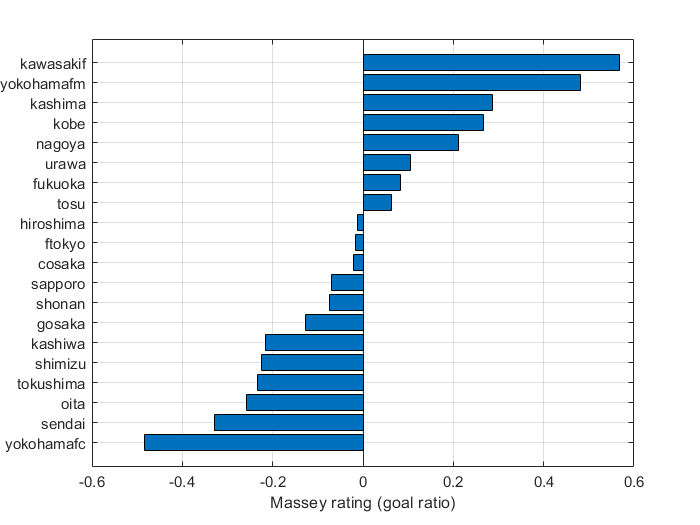

figure;
barh(tbl_teams.Rating);
grid on;
set(gca,'ydir','reverse','fontname','Arial');
yticks(1:size(teamNames,1));
yticklabels(tbl_teams.TeamE);
xlabel('Massey rating (goal ratio)');
exportgraphics(gcf,'GoalRatioRatingSample.pdf');